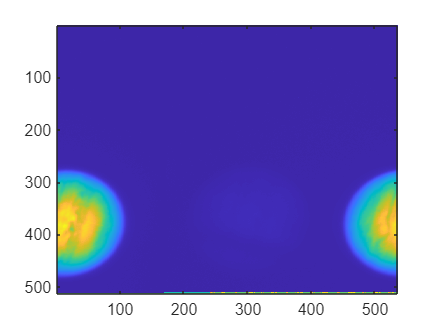

% Brady's code
clc
clear
import matlab.io.*
% **********************************************************************************************
% get a list of all filenames that have "MJD_k_mod" somewhere in their
% filename and end with ".fits" - now the variable "files" is just a 
% list of all the files you want to modify
dataSearch = '*MJD_k_mod*.fits';
files = dir([dataSearch]);
% **********************************************************************************************
% obtain the name of one of the files within the top level variable "files" 
baseFileName = files.name;
%fileattrib(baseFileName,'+w'); 
% **********************************************************************************************
% split the file name into two separate chunks, the chunk before the first
% underscore, and the chunk following the first underscore
split=strsplit(baseFileName,'_');
% take the first of those two chunks
MJD = split{1};
% convert that chunk, now named "MJD" from a string variable to a number
MJD = str2num(MJD);
% call the matlab function "datetime" to convert from MJD to normal time
% (which will be saved as the variable "dt" - then convert the variable
% "dt" from a number type variable to a string type variable
dt = datetime(MJD,'Format','yyyy-MMM-dd hh:mm:ss','ConvertFrom','MJD');
dtstring = datestr(dt);
% **********************************************************************************************
% copy your file over to a temporary holder file that is yours so matlab
% will play nicely with it - I don't know why it wants us to do this 
% actually.
% then, add write permissions to that file
copyfile(baseFileName,'holder1.fits'); 
fileattrib('holder1.fits','+w');
% **********************************************************************************************
% for j = 1:5
%   filename = ['x.' num2str(j) '.fits'];
%   disp(filename)
% end
% 
% for filename = 1:5
% **********************************************************************************************
% open that fits file with both read and write permission
fptr = fits.openFile('holder1.fits','readwrite');
% pull out what the image actually looks like in case you want to see it
imagedata = fits.readImg(fptr);
imagesc(imagedata)

% write the MJD to the header
% **********************************************************************************************
fits.writeComment(fptr,'-----------------------------------------------------------')
fits.writeComment(fptr,'NOTE: IGNORE FIRST DATE LISTED AS (DATE) ABOVE THIS COMMENT')
fits.writeComment(fptr,'-----------------------------------------------------------')
fits.writeComment(fptr,'Target: Jupiter');
% List the target as Jupiter, can be changed for others in future
fits.writeKey(fptr,'MJD',num2str(MJD,15),'Modified Julian Date');
% write the date/time in normal format to the header
fits.writeKey(fptr,'DateTime',dtstring,'dd-MMM-yyyy hh:mm:ss');
% add a comment to the header
% **********************************************************************************************
% copyfile(baseFileName,'holder1.fits'); 
% fileattrib('finishedfile1','+w'); 

%Read the table
EPHEMERIS = readtable('horizonsresultsrevised1.txt') ;


%Pull out specific columns from the JPL Horizons ephemeris file with information you want
EPHEMERIS_TIME=EPHEMERIS(:,1);-2400000.5;
az=EPHEMERIS(:,4)-180;

Operator '-' is not supported for operands of type 'table'.

alt=EPHEMERIS(:,5);

for i = 1:sizeData

     %In the below line, Data_MJD is your specific MJD value for whichever .fits file you are looking at
     % EPHEMERIS_TIME is a variable containing the entire column of all MJD values from your 
     % JPL Horizons ephemeris file (in the "Pull out specific columns" section just above) - 
     % you run the "min" command to say - subtract the MJD I'm looking for from every single 
     % MJD in the entire ephemeris, find the single value where the difference is smaller
     % your two outputs [~,IndexRotation] are going to be that MJD value it found, and then the 
     % index within the array where that value was found. This index is what you need to pull 
     % the matching value later
     [~,IndexRotation] = (min(abs(EPHEMERIS_TIME - Data_MJD(i))));
      
     % now, use that row index to get the other information from the rest of the ephemeris column arrays! 
     az_value = az(IndexRotation);
     az_value = alt(IndexRotation);

end



% filename = 'horizonsresultsrevised1.txt'; % ephemeris file named
% fid = fopen(filename); % open eph file
% 
% % n = strmatch('dt');
% 
% strarray = [];
% x = strmatch(dt, strarray, 'exact');
% disp(x);
% 
% % lines = readlines("horizonsresultsrevised1.txt");
% 
% 
% disp(dt);
% 
% % scan = fscanf(fid,'%s');
% % disp(datescan);
% 
% data=textscan(fid,'dt','delimiter',',');
% % disp(data);
% % string line = data;
% 
% 
% 
% n_line = '1'; % define line to read
% 
% result = textscan(fid, '%s', 1, 'Headerlines', n_line-1, 'Delimiter' ,''); % read eph file line of choice
% result = result{1}; % unbox from cell?
% 
% fclose(fid); % close file
% disp(result);




fitsdisp("holder1.fits");

% close the fits file
fits.closeFile(fptr);

% end